data = load('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\LocCam_calibration.mat');
meer = data.stereoParams;
cameraParams = meer.CameraParameters1;
save('start_positions','-v7.3','-nocompression');


whos

  Name      Size                 Bytes  Class     Attributes

  test      1x1             3307360705  struct              



test = load('all_data.mat')

test = struct with fields:
                                    I: [813×1155 uint8]
                              Params1: [1×1 cameraParameters]
                              Params2: [1×1 cameraParameters]
                                  ans: {[813×1155 uint8]}
                                  cam: [1×1 vision.graphics.Camera]
                             camPoses: [78×2 table]
                            camPoses1: [78×2 table]
                           camPoses10: [90×2 table]
                            camPoses2: [80×2 table]
                            camPoses3: [98×2 table]
                            camPoses4: [100×2 table]
                            camPoses5: [100×2 table]
                            camPoses6: [100×2 table]
                            camPoses7: [96×2 table]
                            camPoses8: [100×2 table]
                            camPoses9: [98×2 table]
                         cameraParams: [1×1 cameraParameters]
                    camera_po

whos

  Name      Size                 Bytes  Class     Attributes

  test      1x1             2920586677  struct              



dir_all = make_dir('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam', 'C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam\')


test.ultimately_used_image_directory1(34)

Reference to non-existent field 'ultimately_used_image_directory11'.

test.final_camera_positions11

%basic tilt is 10
pc1a = last_function(image_directory1, camera_positions1, 8)
pc1b = last_function(image_directory1, camera_positions1, 9)

pc1c = last_function(image_directory1, camera_positions1, 10)
pc1d = last_function(image_directory1, camera_positions1, 11)

pc1e = last_function(image_directory1, camera_positions1, 12)


%save('tussentijds','-v7.3','-nocompression');
%pcshow(pc1)

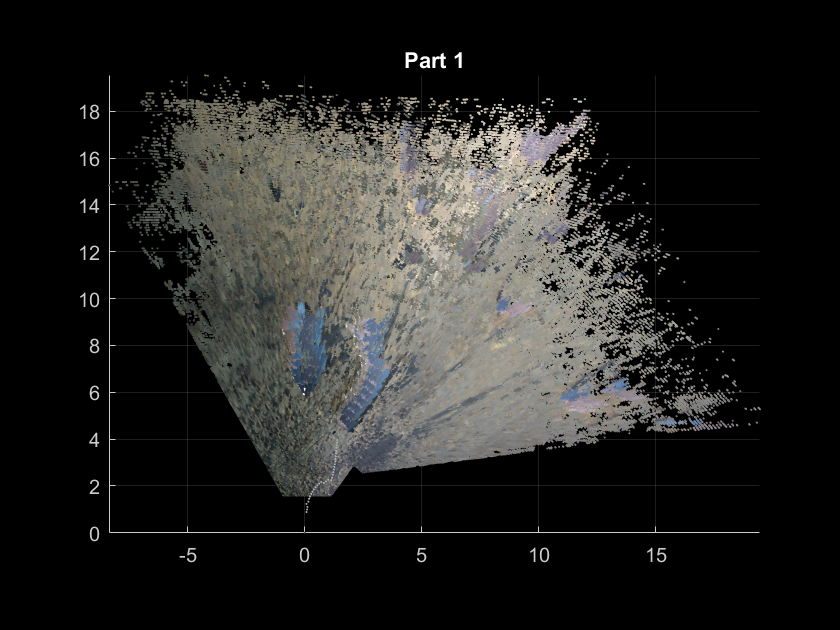

pcshow(test.pc1)
title('Part 1')
view(0, 0)

pcshow(test.pc2)
title('Part 2')
view(0, -90) 

pcshow(test.pc3)
title('Part 3')

pcshow(test.pc4)
title('Part 4')
view(0, 240) 

pcshow(test.pc5)
title('Part 5')
view(0, 0) 

pcshow(test.pc6)
title('Part 6')
view(16, -90)

pcshow(test.pc7)
title('Part 7')
view(90, 0)

pcshow(test.pc8)
title('Part 8')
view(0, 0)

pcshow(test.pc9)
title('Part 9')
view(0, 0)

pcshow(test.pc10)
title('Part 10')

ultimately_used_image_directory2
final_camera_positions2

% pc1 = last_function(ultimately_used_image_directory1, final_camera_positions1)
% save('pc1','-v7.3','-nocompression');

pc2_test = last_function(ultimately_used_image_directory2, final_camera_positions2, 10)
save('pc2','-v7.3','-nocompression');

test.ultimately_used_image_directory3(3:end)
test.final_camera_positions3(3:end)
test.ultimately_used_image_directory3(5:end)

i = {1,2,3,4,5,6,7,8,9,10}

i(5:end)

pc3_test = last_function(test.ultimately_used_image_directory3(30:35), test.final_camera_positions3(30:35), 10)
%save('pc3','-v7.3','-nocompression');

pcshow(pc3_test)
title('Part 3 test')


pc4 = last_function(ultimately_used_image_directory4, final_camera_positions4, 10)
%save('pc4','-v7.3','-nocompression');

pc5 = last_function(ultimately_used_image_directory5, final_camera_positions5, 10)
%save('pc5','-v7.3','-nocompression');

pc6 = last_function(ultimately_used_image_directory6, final_camera_positions6, 10)
%save('pc6','-v7.3','-nocompression');

pc7 = last_function(ultimately_used_image_directory7, final_camera_positions7, 10)
%save('pc7','-v7.3','-nocompression');

pc8 = last_function(ultimately_used_image_directory8, final_camera_positions8, 10)
%save('pc8','-v7.3','-nocompression');

pc9 = last_function(ultimately_used_image_directory9, final_camera_positions9, 10)
%save('pc9','-v7.3','-nocompression');

pc10 = last_function(ultimately_used_image_directory10, final_camera_positions10, 10)
%save('pc10','-v7.3','-nocompression');

save('all_data','-v7.3','-nocompression');

function[ptCloudScene] = last_function(ultimately_used_image_directory, final_camera_positions, tilt)
    
    
    image1 = imread(char(ultimately_used_image_directory(1)));
    imshow(image1)
    
    image2 = imread(char(ultimately_used_image_directory(2)));
    imshow(image2)
    
    pc1 = makePC(char(ultimately_used_image_directory(1)), tilt);
    showPointCloud(pc1)
    pc2 = makePC(char(ultimately_used_image_directory(2)), tilt);
    showPointCloud(pc2)
    ptCloudRef = pc1;
    ptCloudCurrent = pc2;
    
    %tform is the position of the camera as a rigid3d
    ptCloudAligned = pctransform(ptCloudCurrent,final_camera_positions(2));
    
    mergeSize = 0.015;
    ptCloud_firsttwo = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);
    
    showPointCloud(ptCloud_firsttwo)
    
    
    ptCloudScene = ptCloud_firsttwo;
    
    
    pcshow(ptCloud_firsttwo)
    title('first_two');
    for i = 2:(length(ultimately_used_image_directory)-1)
    %get the data of the next timestamp
    i
    ptCloudCurrent = char(ultimately_used_image_directory(i));
    
    PC_next = makePC(ptCloudCurrent, tilt);
    
    ptCloudAligned = pctransform(PC_next, final_camera_positions(i+1));
    
    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene, ptCloudAligned, mergeSize);
    end
    
showPointCloud(ptCloudScene)
end

function [scenePC] = makePC(rangeImageLoc, tilt)
load('.\LocCam_calibration.mat');
if rangeImageLoc(end-4) == '0'
    left_img = imread(rangeImageLoc);
    right_img = imread(strcat(rangeImageLoc(1:end-5),'1.png'));
elseif rangeImageLoc(end-4) == '1'
    left_img = imread(strcat(rangeImageLoc(1:end-5),'0.png'));
    right_img = imread(rangeImageLoc);
else
    disp('No valid image pair was found at this file location.');
    quit;
end

[rectified_left, rectified_right] = rectifyStereoImages(left_img, right_img, stereoParams);

%make dispraity map
disparityMap = disparityBM(rgb2gray(rectified_left), rgb2gray(rectified_right));

%get pointcloud whith depth in meters
tussentijds_xyzPoints = reconstructScene(disparityMap,stereoParams)/1000;

%set depth boundary of 12 meters
Z = tussentijds_xyzPoints(:,:,3);
maskZ = repmat(Z > 0 & Z < 15,[1,1,3]);

%put mask on xyzPoints
tussentijds_xyzPoints(~maskZ) = 0;

scenePC_tussentijds = pointCloud(tussentijds_xyzPoints(:,:,1:3));

angle = -pi/10;
A = [1,0,0,0;0, cos(angle), sin(angle), 0;0, -sin(angle), cos(angle), 0;0 0 0 1];
gedraait = pctransform(scenePC_tussentijds, affine3d(A));

xyzPoints = gedraait.Location;
Y = xyzPoints(:,:,2);
maskY = repmat(Y > 0.5 & Y < 1.4,[1,1,3]);
xyzPoints(~maskY) = 0;

%make xyzPoints into a pointcloud and turn it
scenePC_tussentijds2 = pointCloud(xyzPoints(:,:,1:3));


invert_angle = pi/tilt;
B = [1,0,0,0;0, cos(invert_angle), sin(invert_angle), 0;0, -sin(invert_angle), cos(invert_angle), 0;0 0 0 1];
gedraait2 = pctransform(scenePC_tussentijds2, affine3d(B));

xyzPoints_final = gedraait2.Location;

scenePC = pointCloud(xyzPoints_final, 'Color', rectified_left);
scenePC = removeInvalidPoints(scenePC);
scenePC = pcdenoise(scenePC, 'NumNeighbors',6);
end

function [fill_in_right] = make_dir(location_file, common_directory)

all_data = load('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\LocCam_calibration.mat');
stereParams_data = all_data.stereoParams;
Params1 = stereParams_data.CameraParameters1;
Params2 = stereParams_data.CameraParameters2;

LocCam_file = dir(location_file);
LocCam_image_names = {LocCam_file.name};
LocCam_image_names = LocCam_image_names(3:end);
directory_of_images = {};
%start at 3 because the 1 and 2, are fillers
for i = 1:length(LocCam_image_names)
    if mod(i,2) ~= 0
        name_image = LocCam_image_names(i);
        name_image = char(name_image);
        unique_directory = strcat(common_directory,name_image);
        directory_of_images = [directory_of_images, unique_directory];
    end
end

directory_of_images_small = {};
directory_of_images_small = [directory_of_images_small, directory_of_images(1)];

for i = 1:length(directory_of_images)
    if mod(i,10) == 0
        directory_of_images_small = [directory_of_images_small, directory_of_images(i)];
    end
end
fill_in_right = {};
filler = 'filler';
for i = 1:length(directory_of_images_small)
    fill_in_right = [fill_in_right, directory_of_images_small(i)];
    fill_in_right = [fill_in_right, filler];
end

%directory_of_images_small = directory_of_images_small(1:10);
% 
% image_counter = 1;
% images1 = cell(1, length(directory_of_images_small)*2);
% length(directory_of_images_small)
% for i = 1:length(directory_of_images_small)
%     i
%     [left, right] = rectify(char(directory_of_images_small(i)));
%     images1{image_counter} = left;
%     image_counter  = image_counter + 1;
%     
%     images1{image_counter} = right;
%     image_counter  = image_counter + 1;
% end
end